clear
clear figure;

staticP = zeros(1,11);
totalP = zeros(1, 7);

for i = (1:7)
    data = load("231012_Group05_Subsonic_Total_"+i+".mat");
    
    t = (1:2500);
    
    %data.dataP_mean
    
    %swapping 4 & 5: 
    v = data.dataP_mean(:,4);
    data.dataP_mean(:, 4) = data.dataP_mean(:, 5);
    data.dataP_mean(:, 5) = v;
    
    %swapping 10 & 11: 
    v = data.dataP_mean(:,10);
    data.dataP_mean(:, 10) = data.dataP_mean(:, 11);
    data.dataP_mean(:, 11) = v;
    
    %data.dataP_mean
    %plot(t, dataP_mean);

    staticP = staticP + data.dataP_mean(1:11);
    totalP(i) = data.dataP_mean(12);
    
    %avgP = data.dataP_mean;
    %x = (1:10);
    %plot(x, avgP(1:10))
    %hold on;

    clear data

end

staticP = staticP/7;
totalP;

x = [24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1, 118, 209.5, 300.1];
plot(x(1:7),totalP) 
hold on;
plot(x(1:7),staticP(1:7))
hold off;

g = 1.4

g = 1.4000

R = 8.314/0.02897

R = 286.9865

rho = 1.266 %kg/m^3 at 20 degree C 

rho = 1.2660

M_exp = zeros(1,7);

for i = (1:7)
    M_exp(i) = abs(sqrt( (2/(g-1)) * ( (totalP(i)/staticP(i))^((g-1)/g) -1 )) );
end

%plot(x(1:7), M_exp)

% theoretical calculations: 
% assuming incompressible flow since the experimental dynamic pressure is
% constant everwhere

% using the pressure from pos 2 as reference, vel at that pos:

U_ref = sqrt(2*(totalP(2)-staticP(2)) / rho);

% using coninuity equation:

Ar = [1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28]; % area ratios relative to nozzle
vel = @(n) Ar(n).^(-1) * U_ref;
vel_err = @(n) sqrt( (Ar(n).^(-1) * 0.5.*(pt_err).*4./rho./U_ref).^2);

U = zeros(1,7);
U = vel(1:7);
u_err = vel_err(1:7);

% a = zeros(1:7);
% a = sqrt(g.*staticP(1:7)./rho);
a = sqrt(g*R*298); %/1.12

M_theo = U./a;
m_err_theo = u_err./a;

%finding the P dist: 

pres = @(n) totalP(2) - 0.5*rho*U(n).^2;
pres_err = @(n) sqrt((pt_err^2) + (rho.*U(n).*u_err).^2);

p_theo = zeros(1,7);
p_theo = pres(1:7);
p_err_theo = pres_err(1:7);

p_err_theo = 1.0e+03 *

    1.0558    1.1563    1.0711    0.9375    0.8571    0.8237    0.8160


pt_err = 0.005*103421;

p_err_ex = ones(1,7)*pt_err

p_err_ex =   517.1050  517.1050  517.1050  517.1050  517.1050  517.1050  517.1050



dMp0 = @(n) abs(0.5 .* sqrt( 2/(g-1)) .* sqrt(( (totalP(n)./staticP(n)).^((g-1)/g) -1 ).^(-1)) .* ((g-1)/g) .* (totalP(n)./staticP(n)).^((-1)/g) .* (1./staticP(n)) );
dMp = @(n) abs(0.5 .* sqrt( 2/(g-1)) .* sqrt(( (totalP(n)./staticP(n)).^((g-1)/g) -1 ).^(-1)) .* ((g-1)/g) .* (totalP(n)./staticP(n)).^((-1)/g) .* (-1*totalP(n)./staticP(n).^2) );

m_err_ex = sqrt((dMp0(1:7)*pt_err).^2 + (dMp(1:7)*pt_err).^2);

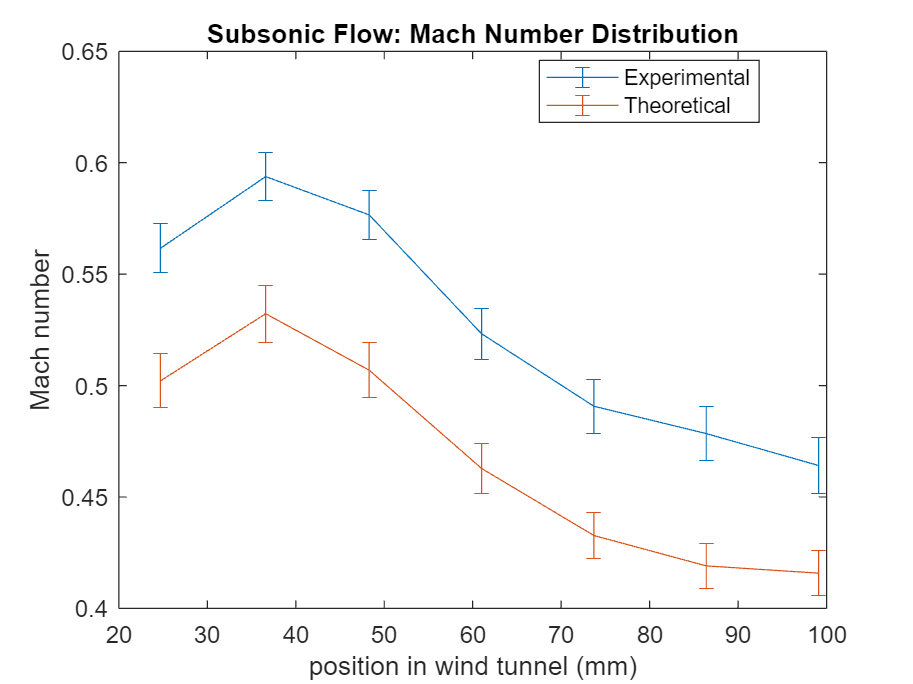

P = zeros(2, 7);
P_error = zeros(2, 7);
y = 1.4;

P(1, :) = staticP(1:7);
P(2, :) = totalP;

%[M_theo, M_error, p_theo, p_error] = subsonic_theo(P, P_error, y)

%hold on;
pl1 = errorbar(x(1:7), M_exp, m_err_ex);
hold on;
pl2 = errorbar(x(1:7), M_theo, m_err_theo);
title("Subsonic Flow: Mach Number Distribution");
legend([pl1(1) pl2(1)],{'Experimental','Theoretical'},'location','best');
xlabel("Position in wind tunnel (mm)");
ylabel("Mach number");
hold off;

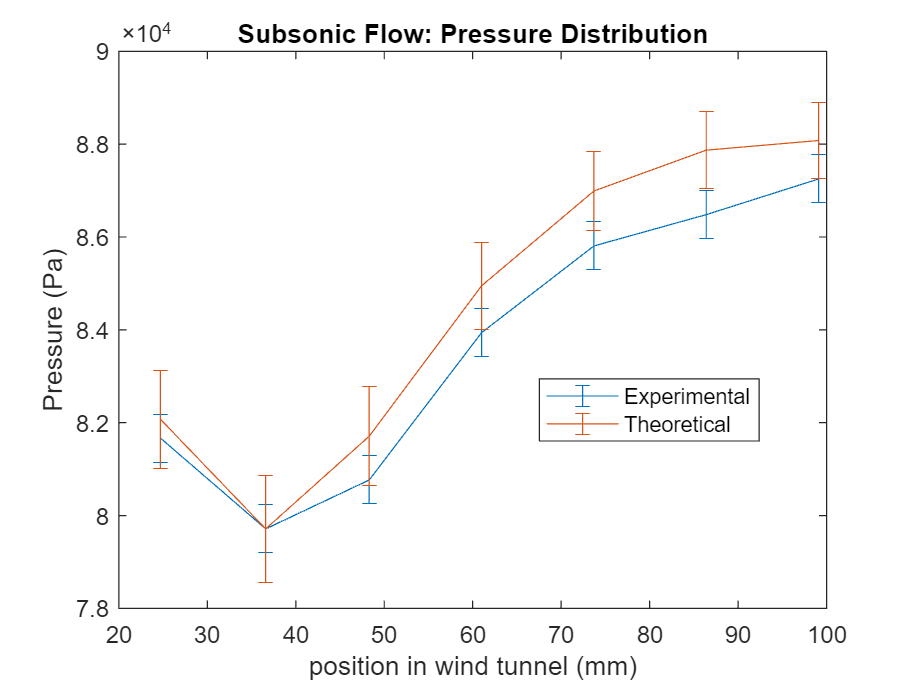


% plot(x(1:7), staticP(1:7), 'DisplayName', 'Experimental');
pl3 = errorbar(x(1:7), staticP(1:7), p_err_ex);
hold on;
pl4 = errorbar(x(1:7), p_theo, p_err_theo);
title("Subsonic Flow: Pressure Distribution");
legend([pl3(1) pl4(1)],{'Experimental','Theoretical'},'location','best');
xlabel("Position in wind tunnel (mm)");
ylabel("Pressure (Pa)");

hold off;

function [M, M_error, p, p_error] = subsonic_theo(P, P_error, g)
    %{
    Inputs
    P : matrix (2, 7)
        Static and total pressures corresponding to each position.
        (1,:): Static port pressures
        (2,:): Total pressures
    P_error : matrix (2, 7)
        Precision uncertainty of static and total pressures
        (1,:): Static port pressures
        (2,:): Total pressures
    g : float
        Ratio of specific heats (gamma).

    Returns
    M : matrix (1, 7)
        The Mach numbers for the input pressure data.
    M_error : matrix (1, 7)
        The Mach number uncertainties.
    p : matrix (1, 7)
        The pressure for the theoretical data.
    p_err : matrix(1, 7)
        Uncertainties associated with the pressures.
    %}

    Ar = [1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28];
    
    p_error = zeros(1, 7);
    p = zeros(1, 7);
    M = zeros(1,7);
    M_error = zeros(1,7);

    for i = 1:7
        f = @(m) (1/m*( (2/(g+1)) * (1 + ((g-1)/2)*m^2) ) ^ ((g+1)/(2*g-2))) - Ar(i);
        if i == 1
            % since flow will likely be subsonic before throat
            [M(i), M_error(i)] = fzero(f, 0.8);
        elseif i == 2
            % since flow will likely be just over Mach 1 at the second tap
            % since its the throat
            [M(i), M_error(i)] = fzero(f, 1);
        else 
            % Subsonic everywhere else
            [M(i), M_error(i)] = fzero(f, 0.7);
        end
    end
    
    h = @(m)(1 + (g - 1)./2 .*m.^2).^(-g ./(g - 1));
    
    p(1, :) = P(2,1) * h(M(1,:));
    
    dp = @(m)-(2.*m.*g*(g./2 - 1./2))./(((g./2 - 1./2).*m.^2 + 1) ...
        .^(g./(g - 1) + 1).*(g - 1));

    p_error = sqrt((h(M) .* P_error(2)).^2 + (dp(M) .* M_error).^2);

    
end
% clear
% load("231012_Group05_Subsonic_Total_1.mat")
% dataP
